# bg pierre

## parametre

h=0.1;
longueur=5;
largeur=6;
laplatempien=-50;
Trouge=20;
Tmarron=15;
np1=longueur/h+1 % nombre des points en longueur du modele

np1 = 131

np2=largeur/h+1 % nombre des points en largeur du modele

np2 = 131

np11=np1-2 % nbr des pts des intemponnus en longueur = inditempe tempolonne = taille de tempomatritempe

np11 = 129

np22=np2-2 % nbr des pts des intemponnus en largeur = inditempe ligne

np22 = 129

## matritempe A

%nbrOfPts=np11+1
A=zeros(np11*np22)

A =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

A1=diag(-4*ones(np11,1))+diag(ones(np11-1,1),-1)+diag(ones(np11-1,1),1)

A1 =     -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -4     1     0     0     0     0     0     0     0     0     0     0  

A2=diag(ones(1,np11))

A2 =      1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0  

for i=1:length(A)/np11 %
    A(1+(i-1)*(np11) : (np11)+(i-1)*(np11)  ,  1+(i-1)*(np11) : (np11)+(i-1)*(np11))=A1;   
end
A

A =     -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -4     1     0     0     0     0     0     0     0     0     0     0   

for i=1:length(A)/np11-1 %
    A((np11+1)+(i-1)*(np11) : 2*(np11)+(i-1)*(np11)  ,  1+(i-1)*(np11) : (np11)+(i-1)*(np11))=A2;
end
A

A =     -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -4     1     0     0     0     0     0     0     0     0     0     0   

for i=1:length(A)/np11-1 %
    A(1+(i-1)*(np11) : (np11)+(i-1)*(np11)  , (np11+1)+(i-1)*(np11) : (np11)*2+(i-1)*(np11))=A2;
end
A

A =     -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     1    -4     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     1    -4     1     0     0     0     0     0     0     0     0     0     0   

imagesc(A)


## vetempteur temp

temp=ones(np22,np11)*h^2*laplatempien;

temp(2:np22,:)=0;
% 4 tempote
temp(1,:)=temp(1,:)-Trouge;
temp(:,1)=temp(:,1)-Tmarron;
size(temp,2)

ans = 129

temp(size(temp,1),:)=temp(size(temp,1),:)-Tmarron;
temp(:,size(temp,2))=temp(:,size(temp,2))-Tmarron;
temp

temp =   -35.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000  -20.5000
  -15.0000         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0  

C=zeros(length(A),1)

C =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


for i=1:size(temp,1)
    C(1+(i-1)*size(temp,2):size(temp,2)+(i-1)*size(temp,2),1)=temp(i,:);
end
C

C =   -35.5000
  -20.5000
  -20.5000
  -20.5000
  -20.5000
  -20.5000
  -20.5000
  -20.5000
  -20.5000
  -20.5000


## Tvec

Tvec=A\C

Tvec =    17.7496
   18.8364
   19.3473
   19.6269
   19.7990
   19.9147
   19.9975
   20.0596
   20.1078
   20.1463


## Zed

Z=zeros(np2,np1)

Z =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

for i=2:size(Z,1)-1 % les ligne
    Z(i, 2:size(Z,2)-1)=Tvec(1+(np11)*(i-2):(np11)+(np11)*(i-2));
end
Z(size(Z,1),:)=Tmarron;
Z(:,1)=Tmarron;
Z(:,size(Z,2))=Tmarron;
Z(1,:)=Trouge;
Z

Z =    20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000   20.0000
   15.0000   17.7496   18.8364   19.3473   19.6269   19.7990   19.9147   19.9975   20.0596   20.1078   20.1463   20.1778   20.2039   20.2260   20.2449   20.2612   20.2754   20.2879   20.2989   20.3088   20.3176   20.3256   20.3328   20.3393   20.3452   20.3507   20.3557   20.3603   20.3645   20.3684   20.3720   20.3753   20.3784   20.3813   20.3840   20.3865   20.3888   20.3910   20.3930   20.3949   20.3967   20.3983   20.3999   20.4013   20.4026   20.4039   20.4050   20.4061   20.4071   20

## graphe

figure(1)
[xq,yq]=meshgrid(0:h:longueur,0:h:largeur)

xq =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000
         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    

yq =          0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    0.1000    

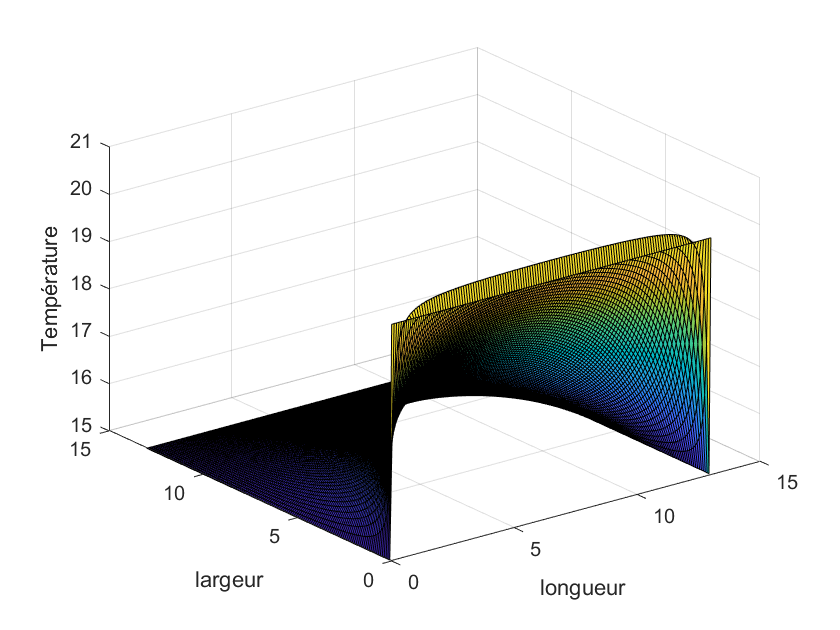

surf(xq,yq,Z)
xlabel('longueur')
ylabel('largeur')
zlabel('Température')

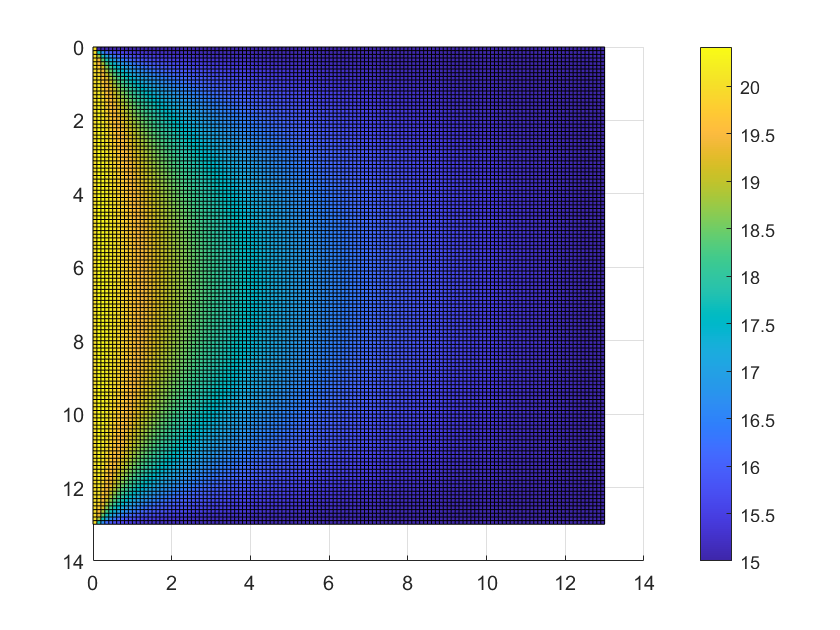


figure(2)
surf(xq,yq,Z)
view([90,90])
colorbar